Constants:

population = 2000000; % 2M people (Slovenia)
sick = [ 10 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ]; % sick how many days
passed = 0; % people who are done with virus
number_of_transmiters = 0;


incubation_period = 6; % days before showing simptoms
percent_of_sympomatic = 0.85; % percent of sick people that develop symptoms
percent_of_asymptomatic = (1 - percent_of_sympomatic);
start_of_contageous_period = 2; % days before being contageous after infection
R0 = 2/7.25; % basic reproduction rate, but it has to be devided by number of days people are contageous
countermeasures = 1; % quarantene, masks, hand washing ... 1 if none at all, 0 if fully effective


recovery_time = 21; % days before recovery if normal
deadth_time = 10; % days before death if in bad health


number_of_sick_asymptomatic = 0;
number_of_sick_symptomatic = 0;
length_of_simulation = 730; 

day = 0;
sick_today = 0;
immune_today = 0;

sick_history = [];
population_history = [];
countermeasures_history = [];
immune_history = [];
new_history = [];

Simulation loop:

while day <= length_of_simulation
        
    sick_loop_index = 1;
    sick_day_before = sick;
    survivors = 0;
    

If day is ... engage countermeasures.

    if day == 30
        countermeasures = 0.3;
    end

Loop over all 21 days on disease trajectory

    for i = sick_day_before
       
        

First move sick patients up a day.

        if sick_loop_index < 21
            
            % move sick patients one day up
            sick( sick_loop_index + 1 ) = sick_day_before (sick_loop_index );
                      
        end
        

Pacients start spreading virus on day 2, mostly stop when they see that they are sick (day 6), some never get simptoms, but are still contageous, they keep spreading virus until they are healty.

                
            % period of transmission before simptoms
            if sick_loop_index == 2 
                
                number_of_transmiters = number_of_transmiters + sick(2);
                
            end
            
            % most people develop symptoms after incubation period
            if sick_loop_index == incubation_period
                
                number_of_transmiters = number_of_transmiters - sick(incubation_period) * percent_of_sympomatic;    
                
            end
            
            % some percent never develops simptoms, that is why they keep
            % spreading disease until they get better
            if sick_loop_index == 21    
                
                number_of_transmiters = number_of_transmiters - sick(21) * percent_of_asymptomatic;
                
            end
            
        

On day 21. sick people become healthy.

        
        % for day 21
        if sick_loop_index == 21
                  
            passed = passed + sick_day_before(21);
       
        end
        

And lastly change to next index in 21 days.

        % counter = counter + 1
        sick_loop_index = sick_loop_index + 1;
    end

Newely infected people:

    
    % new pacients
            sick(1) =  number_of_transmiters * R0 * countermeasures;
            

Number of currently sick people:

    
    sick_today = sick_today + sick(incubation_period) - sick(21);
          

Number of new cases:

    new_today = sick(incubation_period);

Number of imune people:

    immune_today = immune_today + sick(21);

Data for plots:

    sick_history = [sick_history sick_today];
    countermeasures_history = [countermeasures_history 10*countermeasures];
    immune_history = [immune_history immune_today];
    new_history = [new_history new_today];
     

Increment simulation time.

    day = day + 1;
    
end

Make graphs:

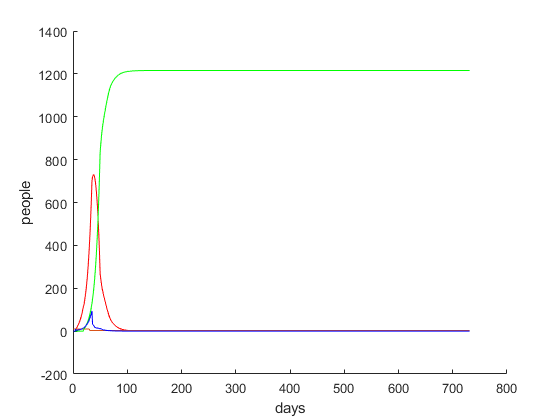

hold on
xlabel('days')
ylabel('people')
plot(sick_history, 'r')
plot(countermeasures_history)
plot(immune_history, 'g')
plot(new_history, 'b')
hold off